## Simulazione

% % % % % Passing from symbolic to real values
% % % % A_real = subs(A,b)
% % % % A_real = double(A_real);
% % % % B_real = double(B);
% % % % C_real = double(C);
% % % % D_real = double(D);
% % % % G_real = collect(simplify(C_real*(s*eye(4)-A_real)^(-1)*B_real+D_real))
% % % % 
% % % % % Coefficients of transfer function (check: seems not correct)
% % % % [num,den] = ss2tf(A_real,B_real,C_real,D_real)
clc
clear
[coeffs_num,coeffs_den] = fdt_vab_lineare(0);

$$G = \frac{5013.0}{40000.0\,s^{2}-4.754e+5}$$

$$num = 25.07$$

$$den = 200.0\,s^{2}-2377.0$$

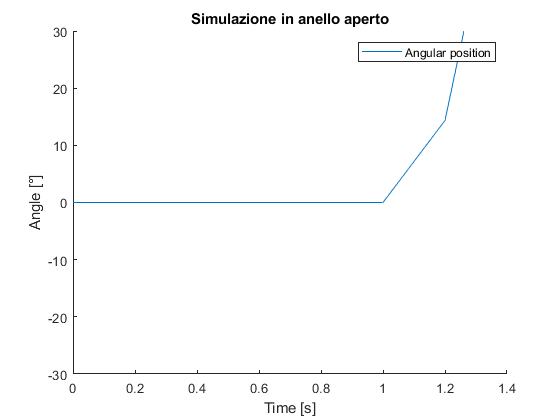


% D1 = -1.0e+10
% K1 = abs(D1);
% D2 = b*1.41e+7/K1
% D3 = 1.184e+11/K1
% D4 = 26620*b/K1
% N1 = -1.438e+9/K1
% N2 = 276e+6*b/K1
% D1 = D1/K1


t_end = 2;
Ts = 1/5;
control_on = 0;
k_p = -1;
sim  VABSim.slx 
clearvars no_control_sim;
no_control_sim(1,:) = sim_res_linear;

figure
hold on
plot(tout, no_control_sim)
xlabel('Time [s]')
ylabel('Angle [°]')
ylim([-30 30])
legend('Angular position')
title('Simulazione in anello aperto')

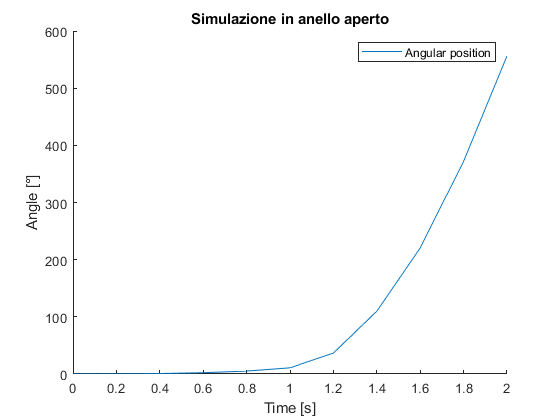


no_control_sim(1,:) = sim_res_NOlinear(:,1);
figure
hold on
plot(tout, no_control_sim)
xlabel('Time [s]')
ylabel('Angle [°]')
legend('Angular position')
title('Simulazione in anello aperto')

control_on = 1;
k_p = 10;

sim  VABSim 

Error in 'VABSim/Interpreted MATLAB Function'. Evaluation of expression resulted in an invalid output. Only finite double vector or matrix outputs are supported

clearvars control_sim;
control_sim(1,:) = sim_res_linear;

figure
hold on
plot(tout, control_sim)
xlabel('Time [s]')
ylabel('Angle [°]')
legend('Angular position')
title('Simulazione con retroazione')

control_sim(1,:) = sim_res_NOlinear(1,:);
figure
hold on
plot(tout, control_sim)
xlabel('Time [s]')
ylabel('Angle [°]')
legend('Angular position')
title('Simulazione con retroazione')

